## Parameters

close all; clear;
%	Approximated based on hardware (DJI F-450 frame w/ 10in propellers) 
l = 0.23;
g = 9.81;
Kt = 0.02;
mass = 0.025;
Ixx = 4e-3;
Iyy = 4e-3;
Izz = 7e-3;
Ib = diag([Ixx Iyy Izz]);
d = -1e-3 * diag([1 1 1.75]);
tau_k = [1  0 -1  0;
	     0 -1  0  1;
		-1  1 -1  1];

n_inputs = 4;			% number of inputs
n_states = 4;			% number of states 4 (vectors)
state_dim = 3;			% dimension of each state

## Dynamics

let the torque kinematics (transform from input to angular acceleration) be

        
$$\tau_k = \pmatrix{1 & 0 & -1 & 0 \cr 0 & -1 & 0 & 1 \cr -1 & 1 & -1 & 1}$$
 

Forces:

	
$$^NT_p = ^N\hat{z}_{B}\; K_t \Sigma^4_{i=1}u_i^2$$


	
$$^B\tau_p = K_t \;l\;\tau_k\;u^2$$


	
$$^NF_g = -massg \hat{z}_N$$


	
$$^NF_w = w_1\hat{x}_N + w_2\hat{y}_N + w_3\hat{z}_N$$


	
$$^B\tau_w = g_1\hat{x}_N + g_2\hat{y}_N + g_3\hat{z}_N$$


	
$$^NF_d = \pmatrix{-d_1 & 0 & 0 \cr 0 & -d_2 & 0 \cr 0 & 0 &-d_3} \; ^N\dot{r}$$
 

	
$$^B\tau_d = \pmatrix{-d_1 & 0 & 0 \cr 0 & -d_2 & 0 \cr 0 & 0 &-d_3} \; \omega$$
 

EOM:

        $\ddot{r} = (T_p + F_g )\; / \; mass$  **Just realized I need to be dividing by the mass (it's pretty late)

        
$$\dot{\omega} = I^{-1}(-[\tilde{\omega}]I\omega +\tau)$$
 

As a state-space model

Let $X = \pmatrix{r \cr \dot{r} \cr q \cr \omega}$

Then,

	
$$\dot{x_1} = x_2$$


	
$$\dot{x_2} = T_p + F_g + F_w + F_d$$


	
$$\dot{x_3} = x_4$$


	
$$\dot{x_4} = I_b^{-1}(-[\tilde{x_4}]\bar{I}x_4+\tau_p + \tau_w + \tau_d)$$


Tried using this diagram to understand the asymmitry in the X and Y axes

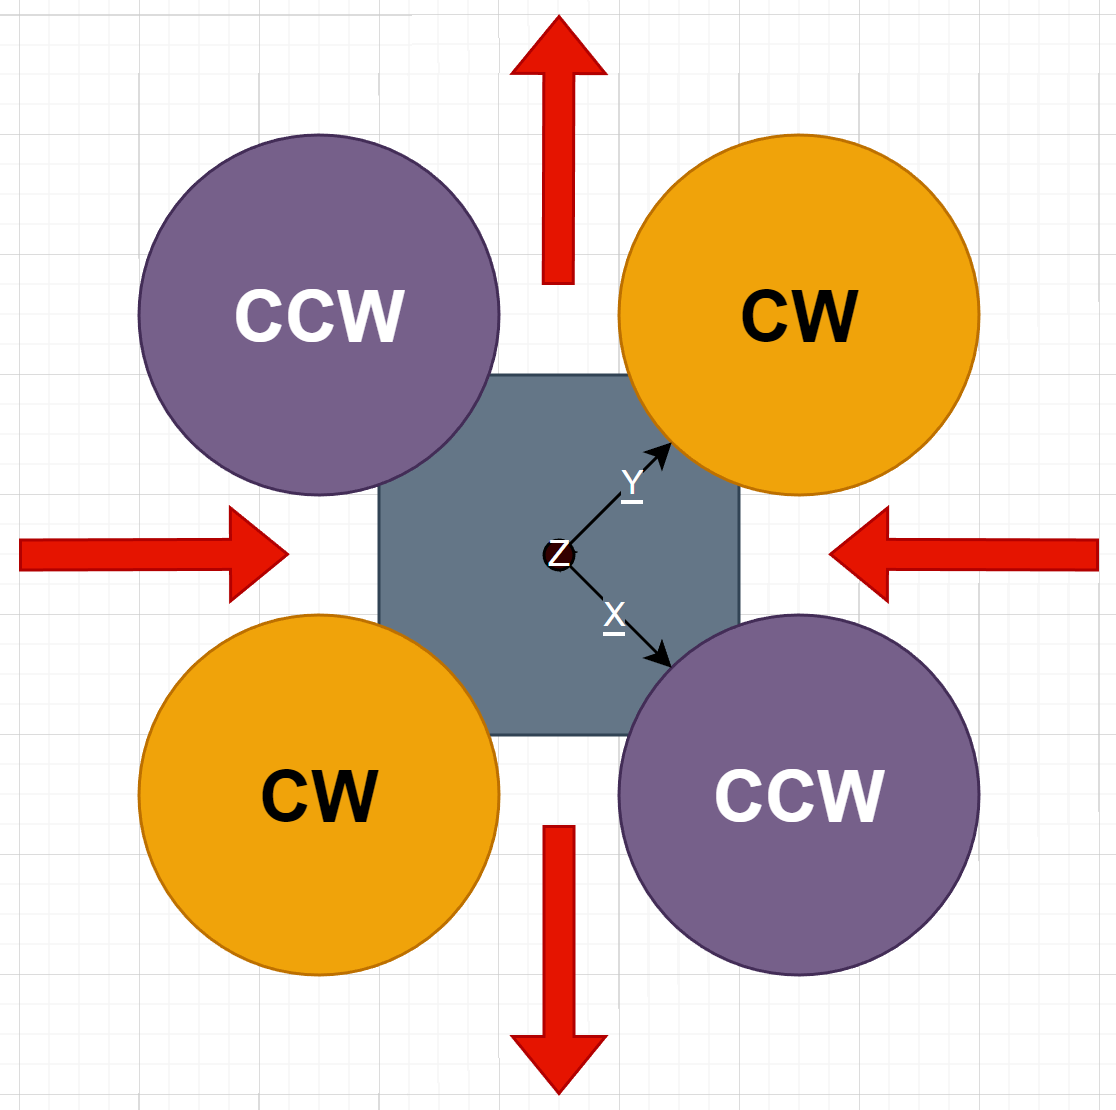

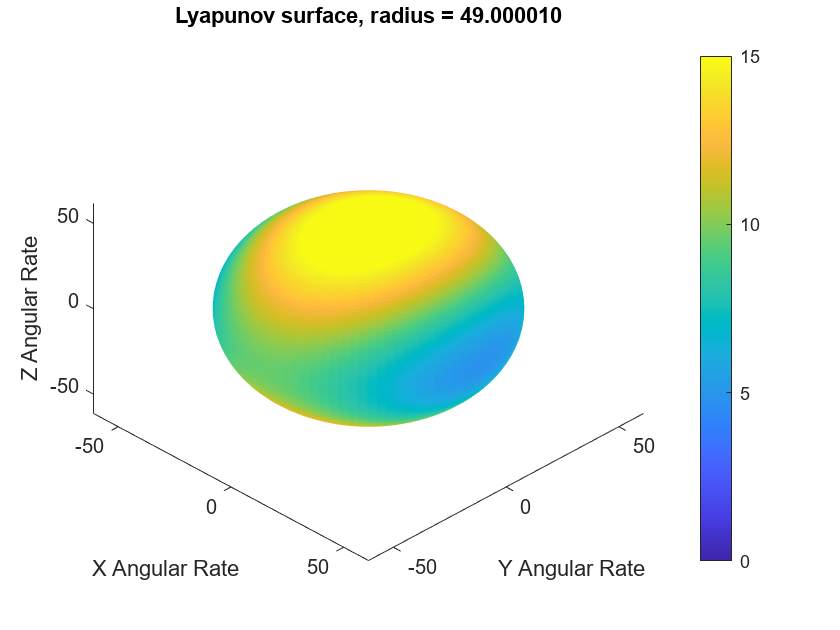

samples = 100;
Zero = zeros(samples, samples);
limits = [-1.25,  1.25];
start_value = 1e-5;
max_value = 50;

figure, hold on
colorbar()
clim([0 15])
xlabel("X Angular Rate")
ylabel("Y Angular Rate")
zlabel("Z Angular Rate")
view([45 45])

for i = start_value:max_value
	[X, Y, Z] = sphere(samples - 1);

	V = Linearized_Lyapunov(Zero, Zero, Zero, Zero, i * X, i * Y, i * Z, mass, Ib);
	s = surf(i * X, i * Y, i * Z, V, "EdgeColor", "none");
	title(sprintf("Lyapunov surface, radius = %f\n", i))
	xlim(i * limits)
	ylim(i * limits)
	zlim(i * limits)
	colorbar()
	pause(0.001);
end

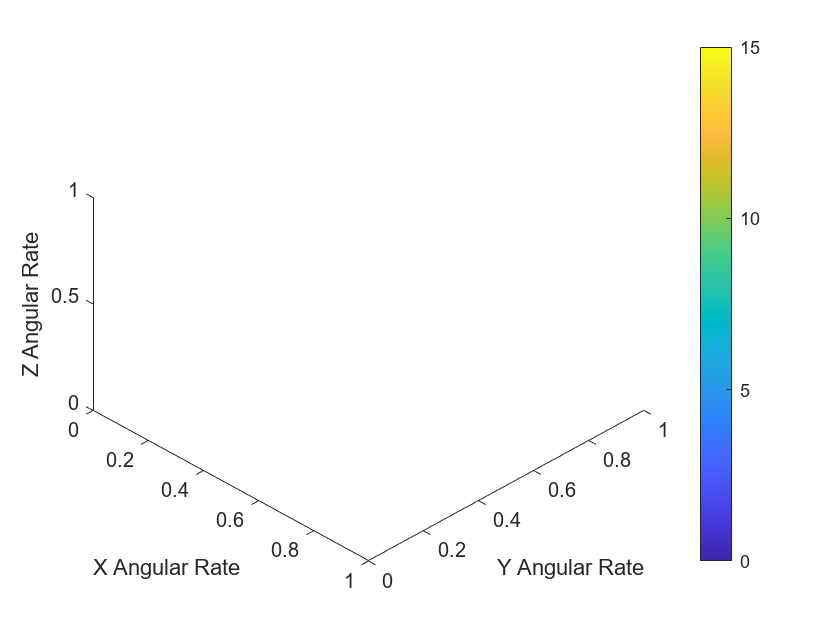

samples = 100;
Zero = zeros(samples, samples);
limits = [-1.25,  1.25];
start_value = 1e-5;
max_value = 50;

figure, hold on
colorbar()
clim([0 15])
xlabel("X Angular Rate")
ylabel("Y Angular Rate")
zlabel("Z Angular Rate")
view([45 45])


for i = start_value:max_value
	[X, Y, Z] = sphere(samples - 1);

	V = Linearized_Lyapunov_dot(i * X, i * Y, i * Z, mass, Ib);
	s = surf(i * X, i * Y, i * Z, V, "EdgeColor", "none");
	title(sprintf("Lyapunov dot surface, radius = %f\n", i))
	xlim(i * limits)
	ylim(i * limits)
	zlim(i * limits)
	colorbar()
	pause(0.001);
end

Unrecognized function or variable 'dwx'.

Error in Linearized_Lyapunov_dot (line 2)
	V = ((Ib(1,1) * wx .* dwx) + (Ib(2,2) * wy .* dwy) + (Ib(3,3) * wz .* dwz));% + (0.5 * mass * (vx.^2 + vy.^2 + vz.^2)) - (9.81 * mass * rz);

$$x2\_dot = \begin{array}{l} \left(\begin{array}{c} 40\,{u_{1}}^{2}\,\sigma_{2}+40\,{u_{2}}^{2}\,\sigma_{2}+40\,{u_{3}}^{2}\,\sigma_{2}+40\,{u_{4}}^{2}\,\sigma_{2}\\ -40\,{u_{1}}^{2}\,\sigma_{1}-40\,{u_{2}}^{2}\,\sigma_{1}-40\,{u_{3}}^{2}\,\sigma_{1}-40\,{u_{4}}^{2}\,\sigma_{1}\\ \frac{4\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,{u_{1}}^{2}}{5}+\frac{4\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,{u_{2}}^{2}}{5}+\frac{4\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,{u_{3}}^{2}}{5}+\frac{4\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,{u_{4}}^{2}}{5}-\frac{981}{100} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)}{50}-\frac{\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{50}\\ \sigma_{2}=\frac{\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)}{50}+\frac{\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)}{50} \end{array}$$

$$x4\_dot = \left(\begin{array}{c} \frac{23\,{u_{1}}^{2}}{20}-\frac{23\,{u_{3}}^{2}}{20}-\frac{3\,w_{2}\,w_{3}}{4}\\ -\frac{23\,{u_{2}}^{2}}{20}+\frac{23\,{u_{4}}^{2}}{20}+\frac{3\,w_{1}\,w_{3}}{4}\\ -\frac{23\,{u_{1}}^{2}}{35}+\frac{23\,{u_{2}}^{2}}{35}-\frac{23\,{u_{3}}^{2}}{35}+\frac{23\,{u_{4}}^{2}}{35} \end{array}\right)$$

$$y = \left(\begin{array}{c} r_{1}\\ r_{2}\\ r_{3}\\ v_{1}\\ v_{2}\\ v_{3}\\ q_{1}\\ q_{2}\\ q_{3}\\ w_{1}\\ w_{2}\\ w_{3} \end{array}\right)$$

$$y\_dot = \left(\begin{array}{c} w_{1}\\ w_{2}\\ w_{3}\\ \frac{23\,{u_{1}}^{2}}{20}-\frac{23\,{u_{3}}^{2}}{20}-\frac{3\,w_{2}\,w_{3}}{4}\\ -\frac{23\,{u_{2}}^{2}}{20}+\frac{23\,{u_{4}}^{2}}{20}+\frac{3\,w_{1}\,w_{3}}{4}\\ -\frac{23\,{u_{1}}^{2}}{35}+\frac{23\,{u_{2}}^{2}}{35}-\frac{23\,{u_{3}}^{2}}{35}+\frac{23\,{u_{4}}^{2}}{35} \end{array}\right)$$

y4 = struct with fields:
    u1: [2×1 sym]
    u3: [2×1 sym]


$$ans = \left(\begin{array}{c} -\frac{\sqrt{23}\,\sqrt{15\,w_{2}\,w_{3}}}{23}\\ \frac{\sqrt{23}\,\sqrt{15\,w_{2}\,w_{3}}}{23} \end{array}\right)$$

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

U2 = struct with fields:
    u1: 0
    u2: 0
    u3: 0
    u4: 0
